clear

p = num_agents x 2 matrix of current agent positions

v = num_agents x 2 matrix of current agent velocities

p_1, p_2, …, p_num_agents = 2 x time matrices hold the historic positions, assigned using a for loop

v_1, v_2, …, v_num_agents =  2 x time matrices hold the historic velocities, assigned using a for loop

p_leader_current = 1x2 vector of the current leader position

p_leader = 2 x time vector of historic leader positions

v_leader_current = 1x2 vector of the current leader velocity

v_leader = 2 x time vector of historic leader velocities

num_agents = 3;
p = zeros(num_agents, 2);
v = zeros(num_agents, 2);
p_leader_current = [0, 0];
v_leader_current = [0, 0];
num_steps = 75;

% x_pos = [ ...
%     0.000, 0.256, 0.435, 0.424, 0.232, ...
%    -0.067, -0.309, -0.288, -0.073, 0.203, ...
%     0.503, 0.770, 0.892, 0.874, 0.656, ...
%     0.357, 0.094, 0.052, 0.212, 0.511 ];
% 
% y_pos = [ ...
%     0.000, 0.143, 0.368, 0.668, 0.898, ...
%     0.937, 0.758, 0.459, 0.251, 0.145, ...
%     0.125, 0.262, 0.537, 0.836, 1.037, ...
%     1.030, 0.879, 0.582, 0.328, 0.278 ];
% 
% x_vel = [ ...
%     0.256, 0.179, -0.011, -0.192, -0.299, ...
%    -0.242, 0.021, 0.215, 0.276, 0.300, ...
%     0.267, 0.122, -0.018, -0.218, -0.299, ...
%    -0.263, -0.042, 0.160, 0.299, 0.298 ];
% 
% y_vel = [ ...
%     0.143, 0.225, 0.300, 0.230, 0.039, ...
%    -0.179, -0.299, -0.208, -0.106, -0.020, ...
%     0.137, 0.275, 0.299, 0.201, -0.007, ...
%    -0.151, -0.297, -0.254, -0.050, 0.058 ];

x_pos = zeros(num_steps, 1);
y_pos = zeros(num_steps, 1);
x_vel = zeros(num_steps, 1);
y_vel = zeros(num_steps, 1);


for i = 1:num_agents
    eval(sprintf('p_%d = [0; 0];', i));
    eval(sprintf('v_%d = [0; 0];', i));
end

p_1 = [1; -1];
p_2 = [-1; -1];
p_3 = [0; -2];
p = [p_1'; p_2'; p_3'];


collision_count = 0;

for i = 1:num_steps
    N = neighbor_calc(p, num_agents);
    v = agent_velocity(N, p, v, p_leader_current, v_leader_current, num_agents);
    p = position_update(p, v);
    
    for j = 1:num_agents
            eval(sprintf('p_%d(:, end+1) = p(%d, :)'';', j, j)); 
            eval(sprintf('v_%d(:, end+1) = v(%d, :)'';', j, j));
    end

    p_leader_current = [x_pos(i), y_pos(i)];
    v_leader_current = [x_vel(i), y_vel(i)];

    collision_radius = 0.05;
    collisions = check_collisions(p, collision_radius);
    if any(collisions(:))
        collision_count = collision_count + 1;
    end
end

disp(['Total Collision Count: ', num2str(collision_count)]);

Total Collision Count: 0


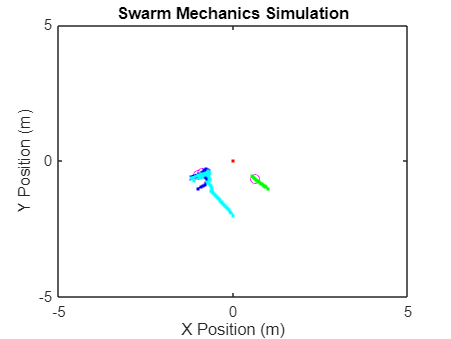


figure;
plot(x_pos, y_pos, 'r.-', "LineWidth", 50); 
hold on;
for i = 1:num_agents
    plot(p(i, 1), p(i, 2), 'mo'); 
    plot(p_1(1, :), p_1(2, :), 'g.-');
    plot(p_2(1, :), p_2(2, :), 'b.-');
    plot(p_3(1, :), p_3(2, :), 'c.-')
end
xlabel('X Position (m)');
ylabel('Y Position (m)');
axis([-5, 5, -5, 5]);
title('Swarm Mechanics Simulation');